clear;close all;

% color representation matrix
cmap = [1 1 1; ...  % 1-white
    0 0 0; ...      % 2-black-static obstacles
    1 0 0; ...      % 3-red-dynamic obstacles
    1 1 0; ...      % 4-yellow-starting position
    1 0 1; ...      % 5-magenta-target position
    0 1 0; ...      % 6-green-planning path
    0 1 1];         % 7-cyan-dynamic planning path

%create color map
colormap(cmap)

%set up a scenario
rows = 10;
cols = 20;

% define raster map and initialize
field = ones(rows, cols);

% obstacle area
obsRate = 0.3;
obsNum = floor(rows*cols *obsRate)  % floor function ensure integer

obsNum = 60

obsIndex = randi([1, rows*cols], obsNum,1)

obsIndex =     25
    99
   171
   175
    55
    42
   113
   129
    84
    42


field(obsIndex) = 2

field =      1     2     2     1     1     1     2     1     1     1     1     1     1     1     1     1     1     2     1     1
     1     1     2     1     2     1     1     1     1     1     1     2     1     1     2     1     1     2     1     1
     1     2     1     1     1     1     1     1     2     2     2     2     1     2     1     2     1     2     1     1
     1     1     2     2     1     1     1     1     2     2     1     1     1     1     1     1     2     1     1     1
     1     1     2     1     1     2     1     1     1     1     1     2     2     1     1     1     1     2     1     1
     2     1     1     2     1     1     1     1     1     1     1     1     1     1     2     1     1     1     1     1
     2     2     2     1     1     1     2     1     1     1     1     1     1     1     1     1     1     1     2     2
     1     1     1     1     1     2     1     1     1     1     2     1     1     1     2     2     1     1     2     2
     1     1     2     1

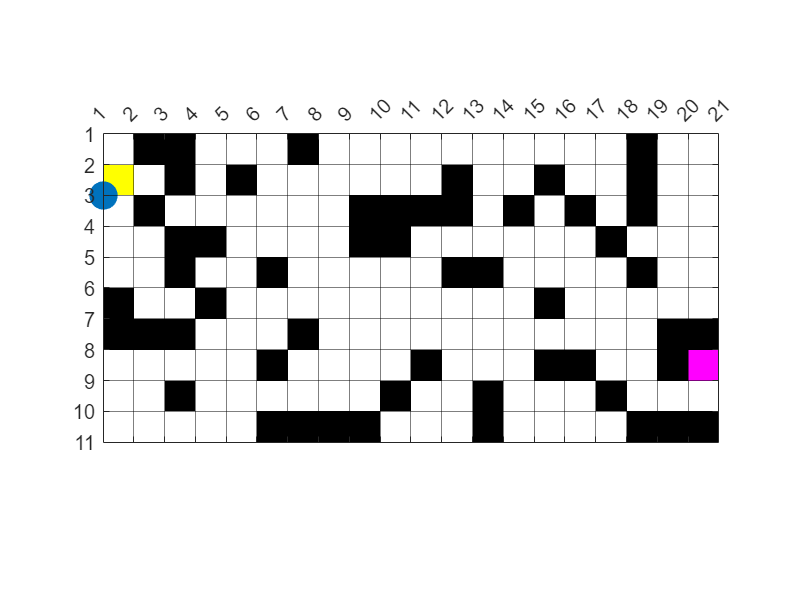


% set starting position and target position
startPos = 2;
goalPos = rows*cols -2;
field(startPos) = 4;
field(goalPos) = 5;

% draw
image(1.5, 1.5, field);
grid on;
hold on;
set(gca, 'gridline', '-', 'gridcolor', 'k', 'linewidth', 0.5, 'GridAlpha', 0.5);
set(gca, 'xtick',1:cols+1,'ytick',1:rows+1);
set(gca, 'XAxisLocation', 'top')
axis image;

scatter(1,3,200,'filled'); % draw a filled circle